# Weighted Average

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

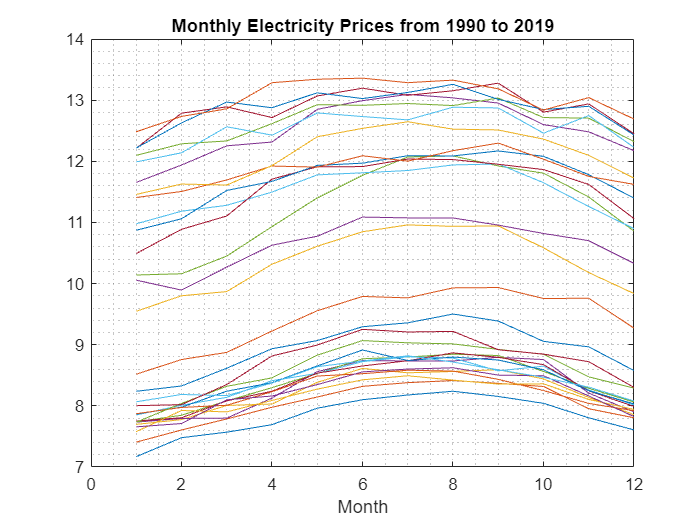

price = readmatrix("./data/electricity.xlsx", Sheet='price');
dollar2019 = readmatrix("./data/electricity.xlsx", Sheet='dollar2019');

plot(price)
grid minor
title("Monthly Electricity Prices from 1990 to 2019")
xlabel("Month")

## Task 1

Calculating the average monthly prices by calculating the average of each row would not take into account that a dollar in 1990 is worth more than a dollar in 2019.

In this practice, you will calculate the weighted average of electricity prices from 1990 to 2019, weighted by the value of 1USD relative to 2019.

First you need to create a weight vector that assigns a percentage of the inflation to each year.

w = (dollar2019 / sum(dollar2019))'

w =     0.0474
    0.0455
    0.0442
    0.0429
    0.0418
    0.0407
    0.0395
    0.0386
    0.0380
    0.0372


## Task 2

a = price * w

a =     9.0773
    9.2490
    9.4388
    9.6565
    9.9222
   10.0782
   10.1100
   10.1400
   10.0803
    9.9163
